n = 400; 

[v,f] = squareMesh3(20);
% v(:,3) = ones(height(v),1);

figure('Position', [1219 773 841 281]); 

nexttile; plotSkeleton(v,f,'view',2);
hold on; scat3(v, 50, 1:height(v), 'filled'); addScatterLabels; 
colorbar; colormap(lines(n)); clim([1 n]);


for ii = 1:20; v(f(ii,:),:) = repmat(v(f(ii,1),:), 3, 1); end
for ii = 21:40; v(f(ii,2),:) = v(f(ii,1),:); end


nexttile; plotSkeleton(v,f,'view',2);
hold on; scat3(v, 50, 1:height(v), 'filled'); addScatterLabels; 
colorbar; colormap(lines(n)); clim([1 n]);

r = coincidentNeighbours(v,f)

r = 34×1 cell array
    {[        395 375]}
    {[        376 357]}
    {[374 373 355 354]}
    {[    372 353 352]}
    {[        371 370]}
    {[        351 331]}
    {[        335 334]}
    {[        318 317]}
    {[        296 295]}
    {[    293 274 273]}
    {[        292 291]}
    {[        278 277]}
    {[        272 271]}
    {[    270 269 250]}
    {[        253 252]}
    {[    248 229 228]}




[v,f] = mergeVerts(v,f,r);

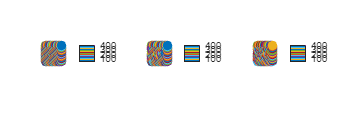



nexttile; plotSkeleton(v,f,'view',2);
hold on; scat3(v, 50, 1:height(v), 'filled'); addScatterLabels; 
colorbar; colormap(lines(n)); clim([1 n]);